# Wildtype data

load('M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\GroupData_paths.mat');
paths = groupData;
[WTgroupHistoL,WTgroupHistoR,WTtotalEvents,WTindividualStats] = analGroupData(paths,0);

## KO Data

load('M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\groupDataKO.mat');
paths = groupDataKO(:,3);
KOgroupHistoL = [];
KOgroupHistoR = [];
KOstatsL = table();
KOstatsR = table();
KOmeanHW = [];
KOtotalEvents = [];
KOgroupAmpL = [];
KOgroupAmpR = [];

for i=1:size(paths)
    load(paths{i});
    [smLIC, peaksBinaryL] = getPeaks(LICmov,0);
    [smRIC, peaksBinaryR] = getPeaks(RICmov,1);
    
    
    [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
    %plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
    
    peaksL = peakStat{1};
    peaksR = peakStat{2};
    KOgroupHistoL = [KOgroupHistoL; peaksL(:,2)];
    KOgroupHistoR = [KOgroupHistoR; peaksR(:,2)];
    KOgroupAmpL = [KOgroupAmpL; i*ones(size(peaksL,1),1), peaksL];
    KOgroupAmpR = [KOgroupAmpR; i*ones(size(peaksR,1),1), peaksR];
    KOtotalEvents = [KOtotalEvents; eventStats];
end

% %% Plots
figure;
histogram([groupHistoL; abs(groupHistoR-125)],25,'faceColor','black','edgeColor','black','faceAlpha',1)
xlim([0,125]);
hold on;
histogram([KOgroupHistoL; abs(KOgroupHistoR-125)],25,'faceColor','red','edgeColor','black','faceAlpha',1)

figure;
ksdensity([groupHistoL; abs(groupHistoR-125)]);
hold on;
yyaxis right;
ksdensity([KOgroupHistoL; abs(KOgroupHistoR-125)]);
% 
% figure;
% histogram([groupAmpR;groupAmpL],'Normalization','cdf');
% hold on;
% histogram([KOgroupAmpR;KOgroupAmpL],'Normalization','cdf');

## Vglut3 data

load('M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\GroupData_paths.mat');
paths = VG3groupData(:,3);

VG3groupHistoL = [];
VG3groupHistoR = [];
VG3groupAmpL = [];
VG3groupAmpR = [];
VG3totalEvents = [];
VG3individualStats = [];


for i=1:size(paths)
    load(paths{i},'-regexp','^(?!LICmov|RICmov)...');
    %[smLIC, peaksBinaryL] = getPeaks(LICmov,0);
    %[smRIC, peaksBinaryR] = getPeaks(RICmov,1);
    
    
    [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
    plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
    VG3individualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmean(eventStats.hwx) size((find(eventStats.numPeaks > 1)),1)/max(eventStats.eventLabel)*100];
    
    peaksL = peakStat{1};
    peaksR = peakStat{2};
    VG3groupHistoL = [VG3groupHistoL; peaksL(:,2)];
    VG3groupHistoR = [VG3groupHistoR; peaksR(:,2)];
    VG3groupAmpL = [VG3groupAmpL; i*ones(size(peaksL,1),1), peaksL];
    VG3groupAmpR = [VG3groupAmpR; i*ones(size(peaksR,1),1), peaksR];
    VG3totalEvents = [VG3totalEvents; eventStats];
    
   
%     tempR = stats;
%     statsR = [statsR; stats];
%     
%     meanHW = [meanHW; mean([tempL.halfwidths;tempR.halfwidths])];
%     totalEvents = [totalEvents; size(tempL.eventLabels,1)];
end

## Salicylate data

load('M:\Bergles Lab Data\Projects\In vivo imaging\Salicylate\GroupData_paths.mat');
paths = SalgroupData(:,3);

SalgroupHistoL = [];
SalgroupHistoR = [];
SalgroupAmpL = [];
SalgroupAmpR = [];
SaltotalEvents = [];
SalindividualStats = [];


for i=1:size(paths)
    load(paths{i},'-regexp','^(?!LICmov|RICmov)...');
    %[smLIC, peaksBinaryL] = getPeaks(LICmov,0);
    %[smRIC, peaksBinaryR] = getPeaks(RICmov,1);
    
    
    [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
    %plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
    SalindividualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmedian(eventStats.hwx)];
    
    peaksL = peakStat{1};
    peaksR = peakStat{2};
    SalgroupHistoL = [SalgroupHistoL; peaksL(:,2)];
    SalgroupHistoR = [SalgroupHistoR; peaksR(:,2)];
    SalgroupAmpL = [SalgroupAmpL; i*ones(size(peaksL,1),1), peaksL];
    SalgroupAmpR = [SalgroupAmpR; i*ones(size(peaksR,1),1), peaksR];
    SaltotalEvents = [SaltotalEvents; eventStats];
    
%     tempR = stats;
%     statsR = [statsR; stats];
%     
%     meanHW = [meanHW; mean([tempL.halfwidths;tempR.halfwidths])];
%     totalEvents = [totalEvents; size(tempL.eventLabels,1)];
end


%%a9 data
% load('M:\Bergles Lab Data\Projects\In vivo imaging\a9 KO\GroupData_paths.mat');
%  paths = a9groupData(:,3);
% 
% a9groupHistoL = [];
% a9groupHistoR = [];
% a9groupAmpL = [];
% a9groupAmpR = [];
% a9totalEvents = [];
% 
% 
% for i=1:size(paths)
%     load(paths{i});
%     [smLIC, peaksBinaryL] = getPeaks(LICmov,0);
%     [smRIC, peaksBinaryR] = getPeaks(RICmov,1);
%     
%     
%     [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
%     %plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
%     
%     peaksL = peakStat{1};
%     peaksR = peakStat{2};
%     a9groupHistoL = [a9groupHistoL; peaksL(:,2)];
%     a9groupHistoR = [a9groupHistoR; peaksR(:,2)];
%     a9groupAmpL = [a9groupAmpL; i*ones(size(peaksL,1),1), peaksL];
%     a9groupAmpR = [a9groupAmpR; i*ones(size(peaksR,1),1), peaksR];
%     a9totalEvents = [a9totalEvents; eventStats];
%     
% %     tempR = stats;
% %     statsR = [statsR; stats];
% %     
% %     meanHW = [meanHW; mean([tempL.halfwidths;tempR.halfwidths])];
% %     totalEvents = [totalEvents; size(tempL.eventLabels,1)];
% end
% 
% close all;

## Bilat Mannitol

ans =          125        6046


ans =          125        6046


pv =     0.1500    0.3000    0.4000    0.6500


ans =          125        6044


ans =          125        6044


pv =     0.1500    0.3000    0.4000    0.6500


ans =          125        6048


ans =          125        6048


pv =     0.1500    0.3000    0.4000    0.6500


ans =          125        6048


ans =          125        6048


pv =     0.1500    0.3000    0.4000    0.6500


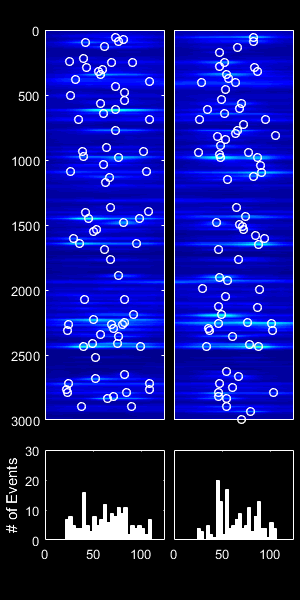

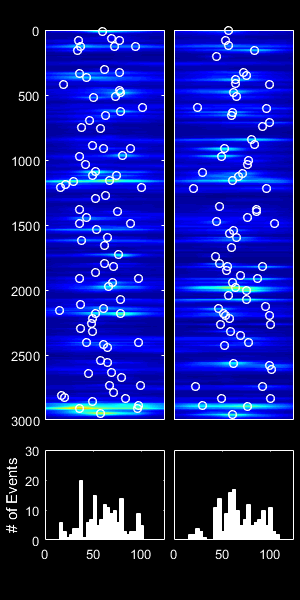

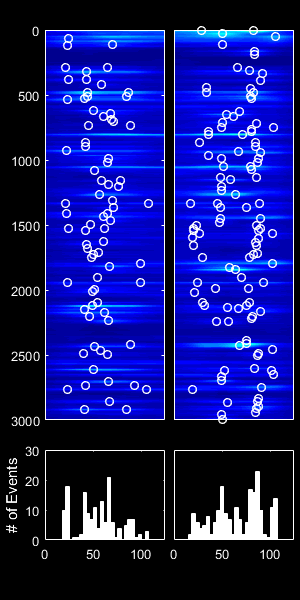

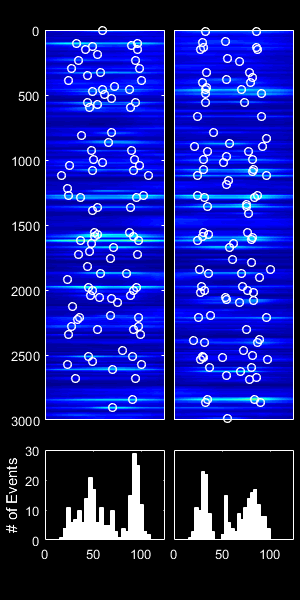

paths = {'564' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-594-Snap25GC6s_mannitol_sham_bilat_PCA\ICmovs_peaks.mat';
         '602' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-602_Snap25GC6s_mannitol_sham_bilat_PCA\ICmovs_peaks.mat';
         '620' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-620_Snap25GC6s_mannitolsham_bilat_PCA\ICmovs_peaks.mat';
         %'622' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-622_Snap25GC6s_mannitolsham_bilat_PCA\ICmovs_peaks.mat'
         '625' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-625_Snap25GC6s_mannitolsham_bilat_2_355_PCA\ICmovs_peaks.mat'
         };
     
[bShamgroupHistoL,bShamgroupHistoR,bShamtotalEvents,bShamindividualStats] = analGroupData(paths,1);

## Bilat MRS2500

ans =          125        6046


ans =          125        6046


pv =     0.1500    0.3000    0.4000    0.6500


ans =          125        6046


ans =          125        6046


pv =     0.1500    0.3000    0.4000    0.6500


ans =          125        6112


ans =          125        6112


pv =     0.1500    0.3000    0.4000    0.6500


ans =          125        6048


ans =          125        6048


pv =     0.1500    0.3000    0.4000    0.6500


ans =          125        6047


ans =          125        6047


pv =     0.1500    0.3000    0.4000    0.6500


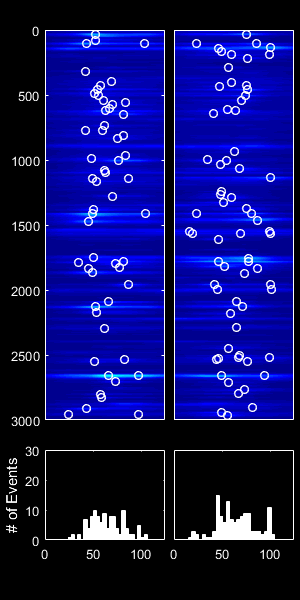

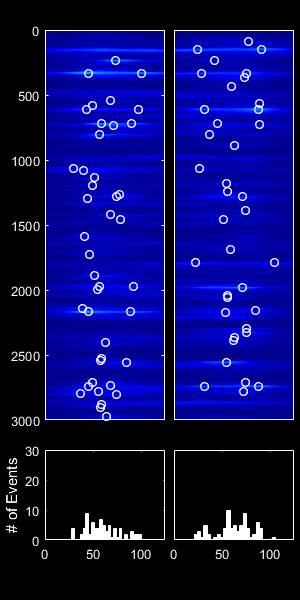

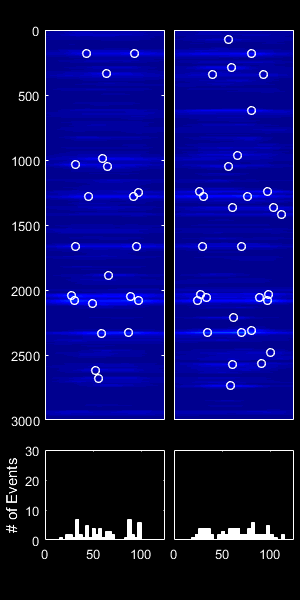

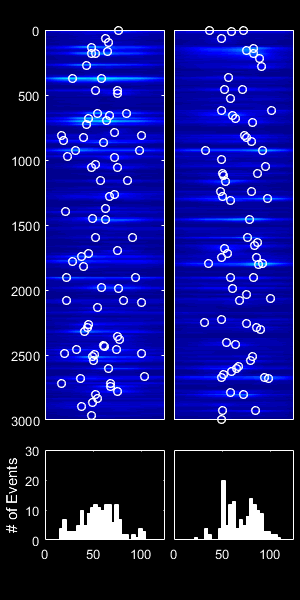

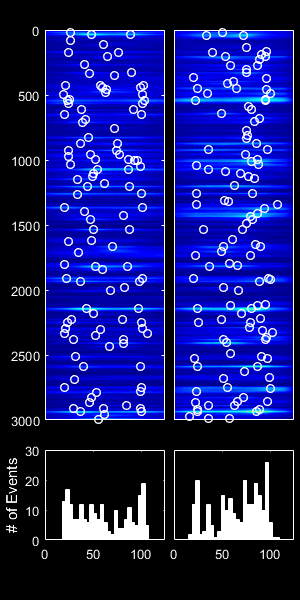

paths = {'592' 'bilat MRS' 'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-592_P7_Snap25GC6s_MRS2500double_PCA\ICmovs_peaks.mat';
         '601' 'bilat MRS' 'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-601_Snap25GC6s_MRS2500_bilat_PCA\ICmovs_peaks.mat';
         '619' 'bilat MRS' 'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-619_Snap25GC6s_MRS2500_bilat_PCA\ICmovs_peaks.mat';
          '622' 'bilat MRS' 'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-623_Snap25GC6s_MRS2500_bilat_PCA\ICmovs_peaks.mat';
           '626' 'bilat MRS' 'C:\Users\Bergles Lab\Desktop\DUP_Experiment-626_Snap25GC6s_MRS2500_bilat_PCA\ICmovs_peaks.mat'
         };
     
[MRSgroupHistoL,MRSgroupHistoR,MRStotalEvents,MRSindividualStats] = analGroupData(paths,1);

## Compare Bilat Mannitol and MRS2500

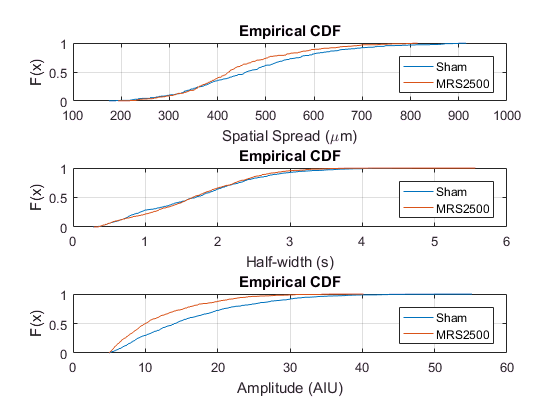

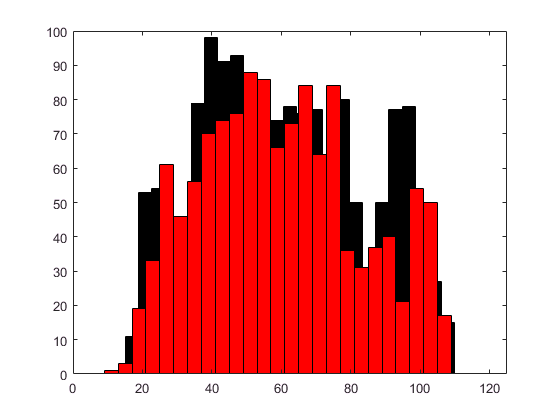

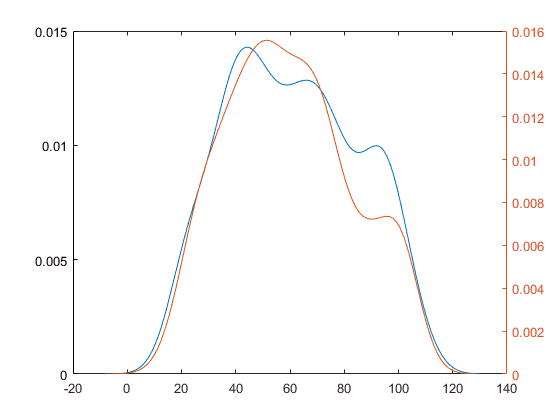

compareFig('Sham', bShamtotalEve      nts, bShamgroupHistoL, bShamgroupHistoR, 'MRS2500', MRStotalEvents, MRSgroupHistoL, MRSgroupHistoR);

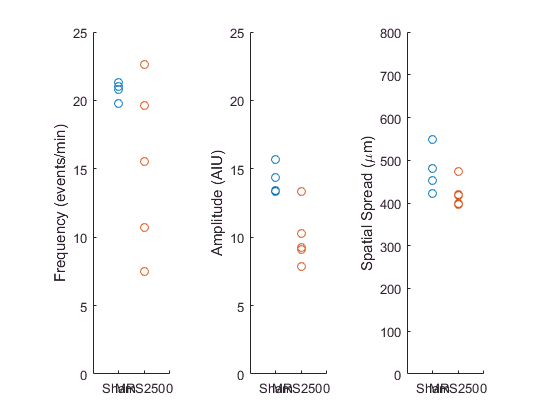

compareStats('Sham', bShamindividualStats, 'MRS2500', MRSindividualStats'''''''''',1);

## Plot

function compareFig(cond1, totalEvents, lHisto, rHisto, cond2, totalEvents2, lHisto2, rHisto2)
    cutoff =0;
    figure;

    subplot(3,1,1);
    cdfplot(totalEvents.hwx(totalEvents.domAmp > cutoff)*7.45);
    hold on;
    cdfplot(totalEvents2.hwx(totalEvents2.domAmp > cutoff)*7.45);
    xlabel('Spatial Spread (\mum)');
    legend(cond1,cond2);
    
    subplot(3,1,2);
    cdfplot(totalEvents.hwt(totalEvents.domAmp > cutoff)/10);
    hold on;
    cdfplot(totalEvents2.hwt(totalEvents2.domAmp > cutoff)/10);
    xlabel('Half-width (s)');
    legend(cond1,cond2);
    
    subplot(3,1,3);
    cdfplot(totalEvents.domAmp);
    hold on;
    cdfplot(totalEvents2.domAmp);
    xlabel('Amplitude (AIU)');
    legend(cond1,cond2);
    
    %%more plot
    figure;
    histogram([lHisto; abs(rHisto-125)],25,'faceColor','black','edgeColor','black','faceAlpha',1)
    xlim([0,125]);
    hold on;
    histogram([lHisto2; abs(rHisto2-125)],25,'faceColor','red','edgeColor','black','faceAlpha',1)
    
    figure;
    ksdensity([lHisto; abs(rHisto-125)]);
    hold on;
    yyaxis right;
    ksdensity([lHisto2; abs(rHisto2-125)]);
end

function compareStats(cond1, indStats, cond2, indStats2, plotFlag)
    m = size(indStats,1);
    m2 = size(indStats2,1);
    
    if(plotFlag)
        figure;
        %frequency
        subplot(1,3,1);
            scatter(ones(m,1), indStats(:,1)/10)
            hold on;
            scatter(2*ones(m2,1), indStats2(:,1)/10)
            ylim([0,25]);
            xlim([0 3]);
            xticklabels({'',cond1,cond2,''});
            ylabel('Frequency (events/min)');
        %amplitude
        subplot(1,3,2);
            scatter(ones(m,1), indStats(:,2))
            hold on;
            scatter(2*ones(m2,1), indStats2(:,2))
            ylim([0,25]);
            xlim([0 3]);
            xticklabels({'',cond1,cond2,''});
            ylabel('Amplitude (AIU)');
        subplot(1,3,3);
            scatter(ones(m,1), indStats(:,4)*7.45)
            hold on;
            scatter(2*ones(m2,1), indStats2(:,4)*7.45)
            ylim([0,800]);
            xlim([0 3]);
            xticklabels({'',cond1,cond2,''});
            ylabel('Spatial Spread (\mum)');
        
    end
end


## Group Data

function [groupHistoL,groupHistoR,totalEvents,individualStats] = analGroupData(paths,plotFlag)
    paths = paths(:,3);
    groupHistoL = [];
    groupHistoR = [];
    totalEvents = [];
    individualStats = [];

    for i=1:size(paths)
        load(paths{i},'-regexp','^(?!LICmov|RICmov)...');
        %load(paths{i});
        %[smLIC, peaksBinaryL] = getPeaks(LICmov,0);
        %[smRIC, peaksBinaryR] = getPeaks(RICmov,1);
        %savefile = '\ICmovs_peaks.mat';
        %[path, fn, ext ] = fileparts(paths{i});
        %save([path savefile],'LICmov','RICmov','smLIC','smRIC','peaksBinaryR','peaksBinaryL');
        size(peaksBinaryR)
        size(peaksBinaryL)
        
        [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
       
        %eventStat = table(eventLabel, eventClassification, leftOrRightDom, numPeaks, domAmp, maxLAmp, maxRAmp,xloc, tloc, hwt, hwx);
        individualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmedian(eventStats.hwx) size((find(eventStats.numPeaks > 1)),1)/max(eventStats.eventLabel)*100];
        peaksL = peakStat{1};
        peaksR = peakStat{2};
        groupHistoL = [groupHistoL; peaksL(:,2)];
        groupHistoR = [groupHistoR; peaksR(:,2)];
        totalEvents = [totalEvents; eventStats];
        
        if(plotFlag)
          plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
        end
    
    end
    
end
